# **RT-QIBC analysis**

**YFP2: EdU**

**FarRed1: geminin IF**

**FarRed2: Cdt1 IF**

**POI(:,3): CRL4Cdt2 activation time**

## **Load Data**

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\';
%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
conditions = {
        'cycling',5:6,2:11,1:4,[0 0 0]; %1
    };



load([dataDir filesep 'C182_data.mat'],'S');
% S = loadData(conditions, dataDir);
framesPerHr = 60/10;
frameDrugAdded = 0;
frameEdU = 0;
timeStart = 3.5;
folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};



**Check stains**

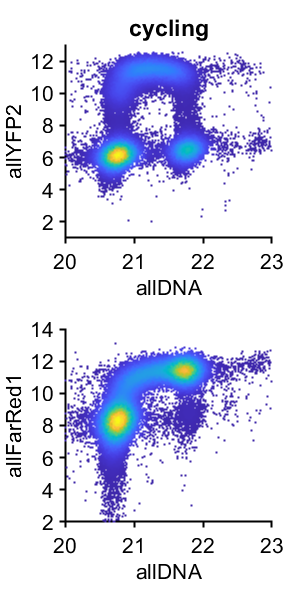

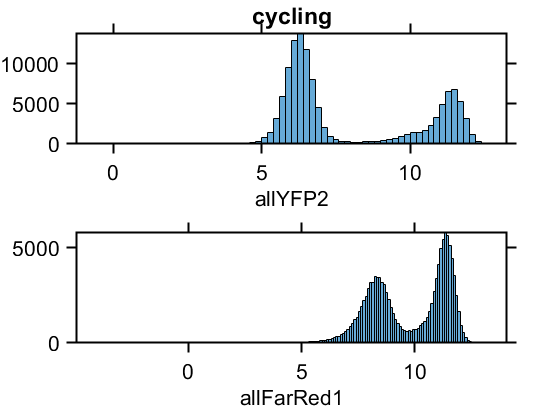

conds=[1];

xval = 'allDNA';
yval = 'allYFP2';
zval = 'allFarRed1';

f1 = figure('pos',[0 0 300 600]); 
f2 = figure;
for i = 1:length(conds)
    condition = conds(i);
    xdata = log2(S(condition).(xval));
    ydata =  real(log2(S(condition).(yval)));
    zdata = real(log2(S(condition).(zval)));
    
    figure(f1)
    subplot(2,length(conds),i)
    dscatter(xdata,ydata);
    xlim([20 23])
    ylim([1 13]);
    ylabel(yval);
    xlabel(xval);
    title(conditions{condition,1});

    figure(f1)
    subplot(2,length(conds),i+length(conds))
    dscatter(xdata,zdata);
    xlim([20 23])
    ylim([2 14]);
    ylabel(zval);xlabel(xval);
    
    figure(f2)
    subplot(2,length(conds),i)
    histogram(ydata)
    xlabel(yval)
    title(conditions{condition,1});

    figure(f2)
    subplot(2,length(conds),i+length(conds))
    histogram(zdata)
    xlabel(zval)
end

**Set gates**

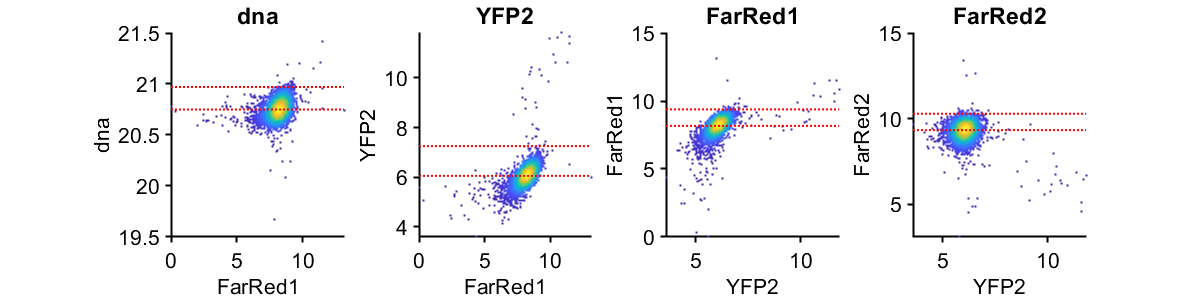


%% Set gates time after mitosis
cond=1;
gate = struct();
gates = {'dna','YFP2','FarRed1','FarRed2'};
plotting = {'FarRed1','FarRed1','YFP2','YFP2'};
prctiles = {[50 99],[50 99],[50 99],[50 99]};

figure('pos',[0 0 length(gates)*300 300 ])

for i = 1:length(gates)
    inds = S(cond).POI_time(:,1) <= 2 & S(cond).POI_time(:,1) > 1 & S(cond).dna < 2^21.5;
    ydata = S(cond).(gates{i})(inds,:);
    xdata = S(cond).(plotting{i})(inds,:);
    
    gate.([gates{i} '_G1']) = prctile(ydata, prctiles{i});
    
    subplot(1,length(gates),i)
    dscatter(log2(xdata),log2(ydata));
    hline( log2(gate.([gates{i} '_G1'])))
    ylabel(gates{i});
    xlabel(plotting{i});
    title(gates{i});
    
    if strcmp(gates{i},'YFP2')
        g1cellsedu = ydata;
    end
    if strcmp(gates{i},'FarRed1')
        g1cellsgem = ydata;
    end
end

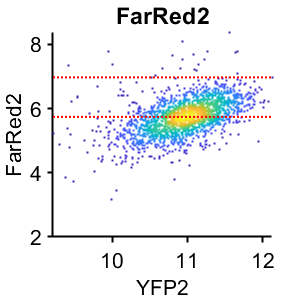



%% set S phase gates
cond=1;
gates = {'FarRed2'};
plotting = {'YFP2'};
prctiles = {[50 99]};

figure('pos',[0 0 length(gates)*300 300 ])

for i = 1:length(gates)
    inds = S(cond).POI_time(:,3) <= 2 &  S(cond).POI_time(:,3) > 1 & S(cond).YFP2 > 2^9 ;
    ydata = S(cond).(gates{i})(inds,:);
    xdata = S(cond).(plotting{i})(inds,:);
    
    gate.([gates{i} '_S']) = prctile(ydata, prctiles{i});
    
    subplot(1,length(gates),i)
    dscatter(log2(xdata),log2(ydata));
    hline( log2(gate.([gates{i} '_S'])))
    
    ylabel(gates{i});
    xlabel(plotting{i});
    title(gates{i});
    
end

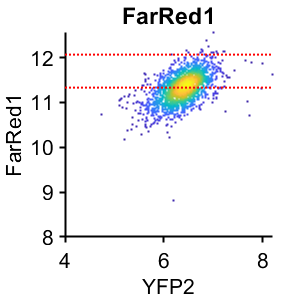


%% set G2 phase gates
cond=1;
gates = {'FarRed1'};
plotting = {'YFP2'};
prctiles = {[50 99]};

figure('pos',[0 0 length(gates)*300 300 ])

for i = 1:length(gates)
    inds = S(cond).POI_time(:,5) > 0 & S(cond).YFP2 < 2*gate.YFP2_G1(2) & S(cond).POI_time(:,3) < 10;
    ydata = S(cond).(gates{i})(inds,:);
    xdata = S(cond).(plotting{i})(inds,:);
    
    gate.([gates{i} '_G2']) = prctile(ydata, prctiles{i});
    
    subplot(1,length(gates),i)
    dscatter(log2(xdata),log2(ydata));
    hline( log2(gate.([gates{i} '_G2'])))
    
    ylabel(gates{i});
    xlabel(plotting{i});
    title(gates{i});
    
    if strcmp(gates{i},'FarRed1')
        g2cellsgem = ydata;
    end

end

**Check GMNN vs EdU levels all cells**

ans =    46.8194    0.3332
   10.7860   42.0614


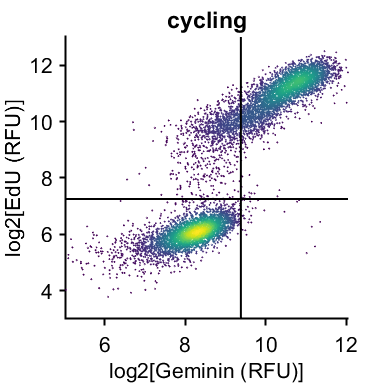

total = 9605

Scells = 3

conds=[1];

xval = 'FarRed1';
yval = 'YFP2';

for i = 1:length(conds)
    condition = conds(i);
    xdata = (log2(S(condition).(xval)));
    ydata =  (log2(S(condition).(yval)));
    %
    % inds = S(condition).dna < 2^21.5;
    inds = S(condition).POI_time(:,1) > 3 & S(condition).POI_time(:,1) < 7 & S(condition).dna < 2^21.4 & S(condition).FarRed1 > 2^5;
    xdata = xdata(inds);
    ydata = ydata(inds);
    
    figure('Units', 'Inches', 'Position', [0, 0, 4, 4]), hold on
    colormap('viridis')
    dscatter(xdata,ydata,'MSIZE',3,'MARKER','o');
% %     xlim([5 13])
    ylim([3 13])
    hline(log2(gate.YFP2_G1(2)),'k');
    vline(log2(gate.FarRed1_G1(2)),'k');
    axis square
    ylabel('log2[EdU (RFU)]');
    xlabel('log2[Geminin (RFU)]');
    title(conditions{condition,1});%h = vline(20.5,'k');v = hline(9,'k');
    
    crosstab(ydata >log2(gate.YFP2_G1(2)), xdata > log2(gate.FarRed1_G1(2)))/length(xdata) * 100

    if condition == 1
        print_pdf([pwd() '\Figs\GMNNvsEdU.pdf'])
        total = length(xdata)
        Scells = sum(xdata<log2(gate.YFP2_G1(2)) & ydata>log2(gate.FarRed1_G1(2)))

    end
end

**stat test gem comparison **

Gate for early mitosis, first .3 hrs, high/low geminin

rng(5)
yval = 'FarRed1';

f1 = figure;
test = {};
ally = [];
group = [];

%%% G1 levels
condition = 1;
ydata = g1cellsgem;
inds = randsample(length(ydata),700);
ydata = ydata(inds);

% ydata(ydata<0) = [];
test{1} = ydata;
ally = [ally; ydata];
group = [group; repmat(1,size(ydata))];

%%% early S phase cells
condition =  1;
ydata = S(condition).(yval);

inds = S(condition).POI_time(:,3) <= 3*10/60 & S(condition).dna < 2^21.25 ;
ydata = ydata(inds);

% ydata(ydata<0) = [];
test{2} = ydata;
ally = [ally; ydata];
group = [group; repmat(2,size(ydata))];


%%% G2 levels
condition = 1;
ydata = g2cellsgem;

% inds = randsample(length(ydata),700);
% ydata = ydata(inds);

test{3} = ydata;
ally = [ally; ydata];
group = [group; repmat(3,size(ydata))];



% ally = ally - median(ally(group ==1));
ally = (ally - median(ally(group == 1)))/(median(ally(group == 3))- median(ally(group == 1)));
test = cellfun(@(x) (x - median(test{1}))/(median(test{3})- median(test{1})),test,'UniformOutput',false);
medians = cellfun(@median,test)

medians =          0    0.0845    1.0000


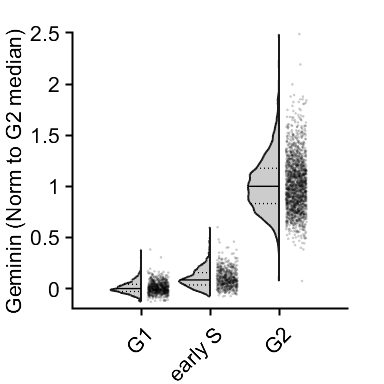


figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1],...
    'xNames',{'G1','early S','G2'});
set(h{1},'EdgeColor',[.1 .1 .1],'LineWidth',1.5)
hold on
jit = 0.3*rand(size(group)) + .1;
scatter(group+jit, (ally), 4,'k','filled','MarkerFaceAlpha',.2);
ylabel('Geminin (Norm to G2 median)')
ylim([-.2 2.5])
xtickangle(45)
pbaspect([1 1 1])

% print_pdf([pwd() '\Figs\gmnn_compare_scatter.pdf'])
